# test_chamfer3

Script for importing data from the following text file:

Auto-generated by MATLAB on 18-Dec-2022 11:59:10

## Set up the Import Options and import the data

clear
opts = delimitedTextImportOptions("NumVariables", 29);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["var_min_air_gap", "var_c_r", "var_c_a", "var_h_C", "var_r_Cout", "var_D_w", "var_t_cfr", "var_t_cfa", "var_t_mba", "var_t_mta", "var_r_A", "var_r_cham", "var_h_cham", "var_t_shell", "var_PR", "var_CSF", "var_h_air", "var_mu", "var_mu0", "var_CWCC", "var_erc", "Nturns", "P", "Ks", "orifice_opening_t", "orifice_closing_t", "total_flow", "total_power", "weight"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
designoptions = readtable("C:\Users\kutla\Documents\GitHub\thesis\test_chamfer3.csv", opts);

## Clear temporary variables

clear opts

total_time = designoptions.orifice_opening_t + designoptions.orifice_closing_t;
for i=1:length(total_time)
    if total_time(i) == 0
        total_time(i) = inf;
    end
end
for i=1:length(designoptions.total_flow)
    if designoptions.total_flow(i) == 0
        designoptions.total_flow(i) = inf;
    end
end
designoptions.total_flow = designoptions.total_flow/designoptions.total_flow(1)-1;
designoptions.weight = designoptions.weight/designoptions.weight(1)-1;
designoptions.orifice_opening_t = designoptions.orifice_opening_t/designoptions.orifice_opening_t(1)-1;
designoptions.orifice_closing_t = designoptions.orifice_closing_t/designoptions.orifice_closing_t(1)-1;

control_auth = designoptions.total_flow ./ total_time;
control_auth = control_auth / control_auth(1);
peak_control_auth = find(max(control_auth) == control_auth,1)

peak_control_auth = 7

designoptions(peak_control_auth,:)

ans = 1×29 table
    var_min_air_gap    var_c_r    var_c_a    var_h_C    var_r_Cout    var_D_w    var_t_cfr    var_t_cfa    var_t_mba    var_t_mta    var_r_A    var_r_cham    var_h_cham    var_t_shell    var_PR    var_CSF    var_h_air    var_mu     var_mu0      var_CWCC    var_erc     Nturns        P         Ks      orifice_opening_t    orifice_closing_t    total_flow    total_power    weight
    _______________    _______    _______    _______

fastest = find(min(total_time) == total_time,1)

fastest = 31

designoptions(fastest,:)

ans = 1×29 table
    var_min_air_gap    var_c_r    var_c_a    var_h_C    var_r_Cout    var_D_w    var_t_cfr    var_t_cfa    var_t_mba    var_t_mta    var_r_A    var_r_cham    var_h_cham    var_t_shell    var_PR    var_CSF    var_h_air    var_mu     var_mu0      var_CWCC    var_erc     Nturns        P         Ks      orifice_opening_t    orifice_closing_t    total_flow    total_power    weight
    _______________    _______    _______    _______

min_flow = find(min(designoptions.total_flow) == designoptions.total_flow,1)

min_flow = 31

designoptions(min_flow,:)

ans = 1×29 table
    var_min_air_gap    var_c_r    var_c_a    var_h_C    var_r_Cout    var_D_w    var_t_cfr    var_t_cfa    var_t_mba    var_t_mta    var_r_A    var_r_cham    var_h_cham    var_t_shell    var_PR    var_CSF    var_h_air    var_mu     var_mu0      var_CWCC    var_erc     Nturns        P         Ks      orifice_opening_t    orifice_closing_t    total_flow    total_power    weight
    _______________    _______    _______    _______

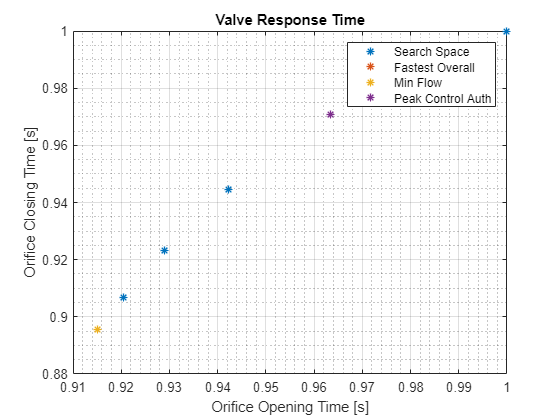

plot(designoptions.orifice_opening_t,designoptions.orifice_closing_t,...
    designoptions.orifice_opening_t(fastest),designoptions.orifice_closing_t(fastest),...
    designoptions.orifice_opening_t(min_flow),designoptions.orifice_closing_t(min_flow),...
    designoptions.orifice_opening_t(peak_control_auth),designoptions.orifice_closing_t(peak_control_auth),...
    "LineStyle","none","Marker", "*","MarkerSize",6,LineWidth=1)
%xlim([0 inf]),ylim([0 inf])
grid on, grid minor
xlabel('Orifice Opening Time [s]'),ylabel('Orifice Closing Time [s]'),title('Valve Response Time'),legend('Search Space','Fastest Overall','Min Flow','Peak Control Auth')

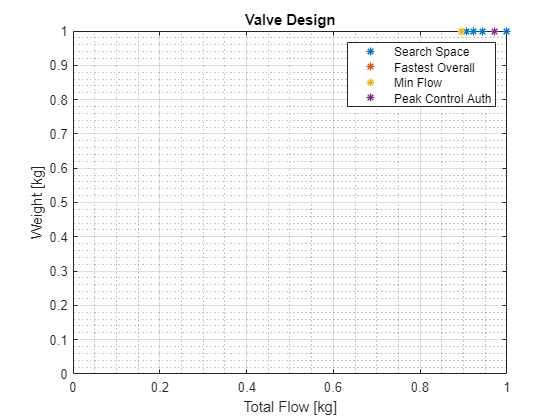

plot(designoptions.total_flow,designoptions.weight,...
    designoptions.total_flow(fastest),designoptions.weight(fastest),...
    designoptions.total_flow(min_flow),designoptions.weight(min_flow),...
    designoptions.total_flow(peak_control_auth),designoptions.weight(peak_control_auth),...
    "LineStyle","none","Marker", "*","MarkerSize",6,LineWidth=1)
xlim([0 inf]),ylim([0 inf])
grid on, grid minor
xlabel('Total Flow [kg]'),ylabel('Weight [kg]'),title('Valve Design'),legend('Search Space','Fastest Overall','Min Flow','Peak Control Auth')

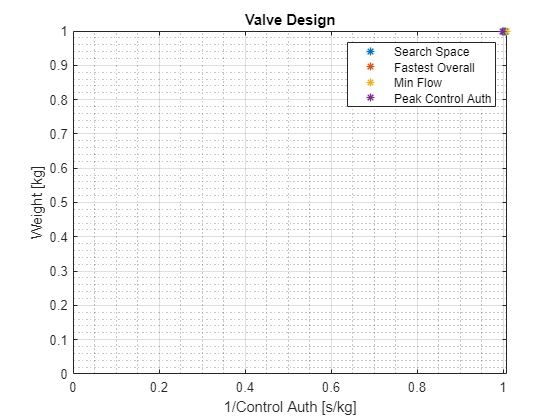

plot(1./control_auth,designoptions.weight,...
    1./control_auth(fastest),designoptions.weight(fastest),...
    1./control_auth(min_flow),designoptions.weight(min_flow),...
    1./control_auth(peak_control_auth),designoptions.weight(peak_control_auth),...
    "LineStyle","none","Marker", "*","MarkerSize",6,LineWidth=1)
xlim([0 inf]),ylim([0 inf])
grid on, grid minor
xlabel('1/Control Auth [s/kg]'),ylabel('Weight [kg]'),title('Valve Design'),legend('Search Space','Fastest Overall','Min Flow','Peak Control Auth')

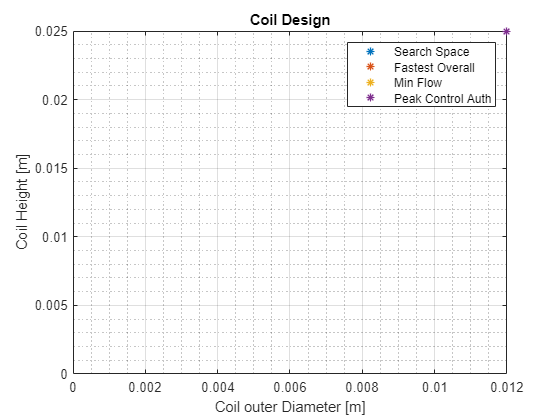

plot(designoptions.var_r_Cout,designoptions.var_h_C,...
    designoptions.var_r_Cout(fastest),designoptions.var_h_C(fastest),...
    designoptions.var_r_Cout(min_flow),designoptions.var_h_C(min_flow),...
    designoptions.var_r_Cout(peak_control_auth),designoptions.var_h_C(peak_control_auth),...
    "LineStyle","none","Marker", "*","MarkerSize",6,LineWidth=1)
xlim([0 inf]),ylim([0 inf])
grid on, grid minor
xlabel('Coil outer Diameter [m]'),ylabel('Coil Height [m]'),title('Coil Design'),legend('Search Space','Fastest Overall','Min Flow','Peak Control Auth')

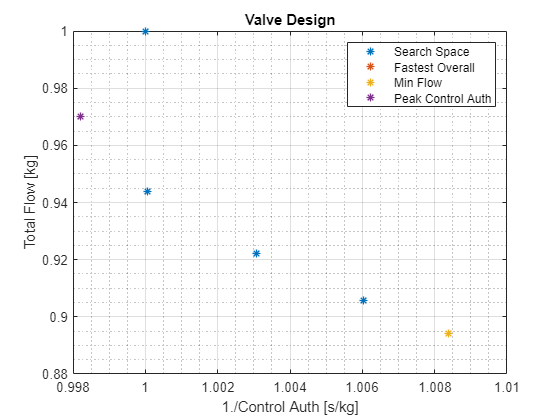

plot(1./control_auth,designoptions.total_flow,...
     1./control_auth(fastest),designoptions.total_flow(fastest),...
     1./control_auth(min_flow),designoptions.total_flow(min_flow),...
     1./control_auth(peak_control_auth),designoptions.total_flow(peak_control_auth),...
    "LineStyle","none","Marker", "*","MarkerSize",6,LineWidth=1)
%xlim([0 inf]),ylim([0 inf])
grid on, grid minor
xlabel('1./Control Auth [s/kg]'),ylabel('Total Flow [kg]'),title('Valve Design'),legend('Search Space','Fastest Overall','Min Flow','Peak Control Auth')

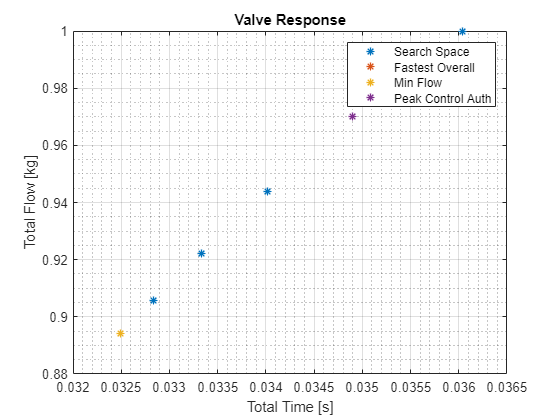

plot(total_time,designoptions.total_flow,...
    total_time(fastest),designoptions.total_flow(fastest),...
    total_time(min_flow),designoptions.total_flow(min_flow),...
    total_time(peak_control_auth),designoptions.total_flow(peak_control_auth),...
    "LineStyle","none","Marker", "*","MarkerSize",6,LineWidth=1)
%xlim([0 inf]),ylim([0 inf])
grid on, grid minor
xlabel('Total Time [s]'),ylabel('Total Flow [kg]'),title('Valve Response'),legend('Search Space','Fastest Overall','Min Flow','Peak Control Auth')

%xlswrite('params.xlsx',[designoptions.Properties.VariableNames;table2array(designoptions(peak_control_auth,:));strings([1,length(designoptions.Properties.VariableNames)])+'m']')